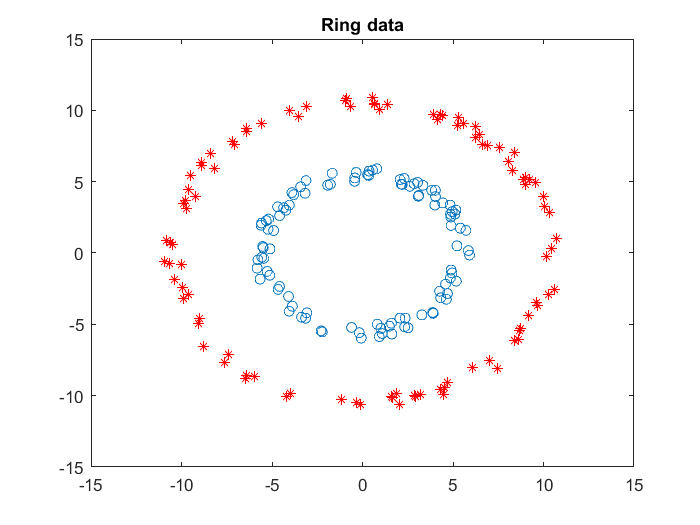

clear all;
clc;

d = 100;
r1 = 5+rand(d,1);
theta = 2*pi*rand(d,1);
x1 = r1.*cos(theta);
y1 = r1.*sin(theta);
 
r2 = 10+rand(d,1);
x2 = r2.*cos(theta);
y2 = r2.*sin(theta);
figure(3)
plot(x1,y1,'o');hold on;
plot(x2,y2,'*','Color','red');title('Ring data')
hold off;

A=[x1 y1; x2 y2]; 
c=ones(d,1);        
class=[c;-c];

x = A;
y = class;

[n d]=size(x);

m=nonlinear_svm(x,y,1,1);

 
Calling SDPT3 4.0: 403 variables, 201 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 201
 dim. of socp   var  = 202,   num. of socp blk  =  1
 dim. of linear var  = 200
 dim. of free   var  =  1 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.7e+01|1.0e+02|8.0e+04| 0.000000e+00  0.000000e+00| 0:0:00| chol  1  1 
 1|0.378|0.378|1.7e+01|6.2e+01|5.9e+04| 2.221311e+02  1.423635e+02| 0:0:01| chol  1  1 
 2|0.422|0.421|9.8e+00|3.6e+01|4.0e+04| 7.752881e+02 -2.166808e+02| 0

y_pred=sign(svmPredict(x,m));
for i=1:size(y_pred)
    if y_pred(i)==1
    y_pred(i)=1;
    else
    y_pred(i)=-1;
    end
end

count=0;
for i=1:size(y_pred)
    if y_pred(i)==y(i)
        count=count+1;
    end
end
fprintf("Accuracy is");disp(count/200*100)

Accuracy is   100



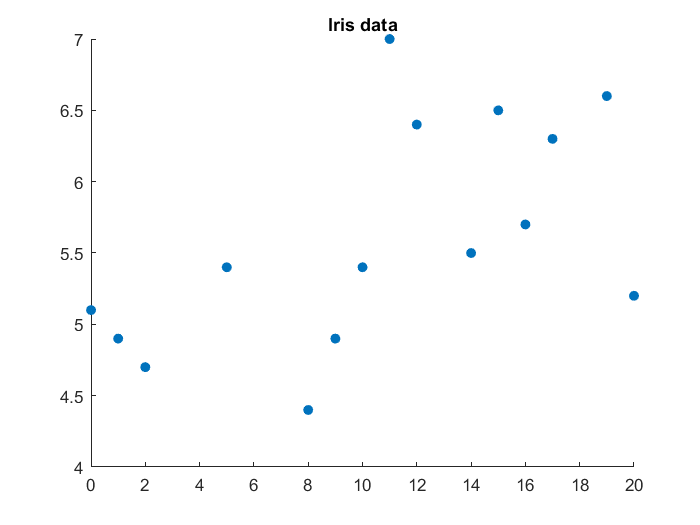

clear all;
clc;

% importing data
X_train = readmatrix("Xtrain.csv");
y_train = readmatrix("ytrain.csv");

% x --> features , y --> label
x = X_train(:,1:4);
x = x(2:end,:);
y = y_train(2:end,2:end);

scatter(x(:,1),x(:,2),'filled')
title('Iris data')
hold off

[n d]=size(x);

m=nonlinear_svm(x,y,5,1);

 
Calling SDPT3 4.0: 48 variables, 16 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 16
 dim. of socp   var  = 17,   num. of socp blk  =  1
 dim. of linear var  = 30
 dim. of free   var  =  1 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|1.0e+00|4.9e+00|6.7e+03| 8.215838e+02  0.000000e+00| 0:0:00| chol  1  1 
 1|0.747|0.750|2.5e-01|1.2e+00|2.5e+03| 8.514215e+02  7.238417e+00| 0:0:00| chol  1  1 
 2|0.868|0.650|3.3e-02|4.3e-01|1.3e+03| 7.281997e+02 -9.197650e+00| 0:0:01

X_test = readmatrix("Xtest.csv"); 
y_test = readmatrix("ytest.csv"); 
testx = X_test(2:end,1:4);
testy = y_test(2:end,2:end);

y_pred=sign(svmPredict(testx,m))

y_pred =      0
     0
     1
     0
     0
     1
     1


for i=1:size(y_pred)
    if y_pred(i)==1
    y_pred(i)=1;
    else
    y_pred(i)=-1;
    end
end

count=0;
for i=1:size(y_pred)
    if y_pred(i)==testy(i)
        count=count+1;
    end
end
fprintf("Accuracy is");disp(count/7*100)

Accuracy is   100



function model = nonlinear_svm(X,Y,C,sigma)

% Nonlinear SVM with RBF Kernel
N = size(X,1);
K = zeros(N,N);
for i=1:N % RBF kernel
    for j = 1:N
            K(i,j) = exp(-1*sum((X(i,:)-X(j,:)).^2)/(2*(sigma)^2));
    end 
end

cvx_begin
    cvx_precision best
    variable a_m(N);
    minimize (0.5.*quad_form(Y.*a_m,K) - ones(N,1)'*(a_m));
    subject to
        a_m >= 0;
        Y'*(a_m) == 0;
        a_m <= C*ones(N,1);
cvx_end

a_m(a_m<10^-5)=0;
%X_m = X(a_m > 0,:);
%Y_m = Y(a_m > 0);
%a_m = a_m(a_m > 0);

K=zeros(length(X(:,1)),length(X(:,1)));
for i=1:length(X(:,1)) % RBF kernel
    for j = 1:length(X(:,1))
            K(i,j) = exp(-1*sum((X(i,:)-X(j,:)).^2)/(2*(sigma)^2));
    end 
end

b_m = mean(Y-K*(a_m.*Y));

model = getModel(X, Y, a_m, b_m, sigma, "nonlinear");

end

function model = getModel(X_m, Y_m, a_m, b_m, s_m, type)
    model.type = type;
    model.X = X_m;
    model.Y = Y_m;
    model.a = a_m;
    model.b = b_m;
    model.s = s_m;
end

function predictions = svmPredict(X, model)
    if model.type == "nonlinear"
    K=zeros(length(X(:,1)),length(model.X(:,1)));
    for i=1:length(X(:,1))% RBF kernel
        for j = 1:length(model.X(:,1))
               K(i,j) = exp(-1*sum((X(i,:)-model.X(j,:)).^2)/(2*(model.s)^2));
           end
       end
       predictions = K *(model.a.*model.Y) - model.b>0;
    end
end